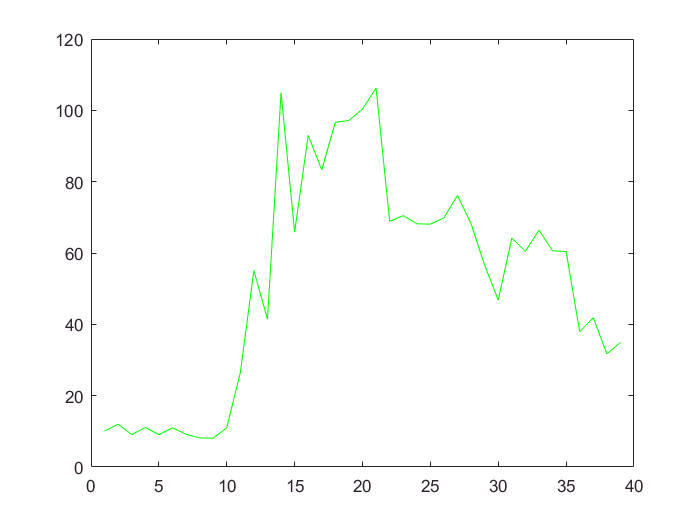

% plots actual traces
load('C:\Users\seanm\Desktop\garcia_lab_stuff\elong_search\dat\real_data\processed_data.mat');
i = 19;
data = preprocessed(i);

figure;
plot(data.green98, 'g');

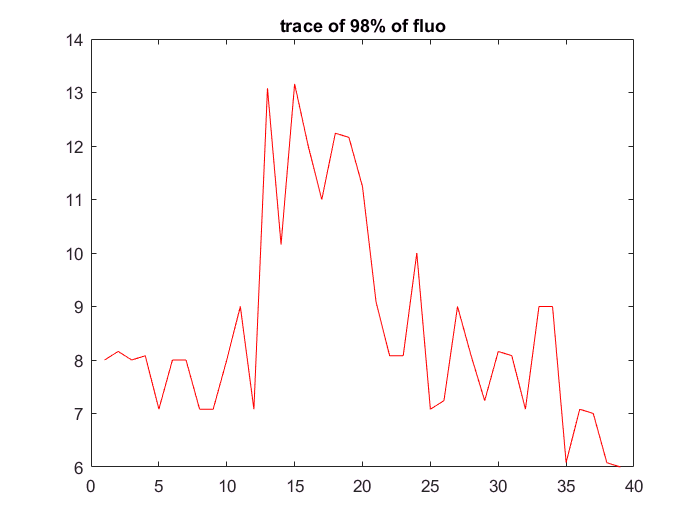

figure;
plot(data.red98, 'r');
title('trace of 98% of fluo');

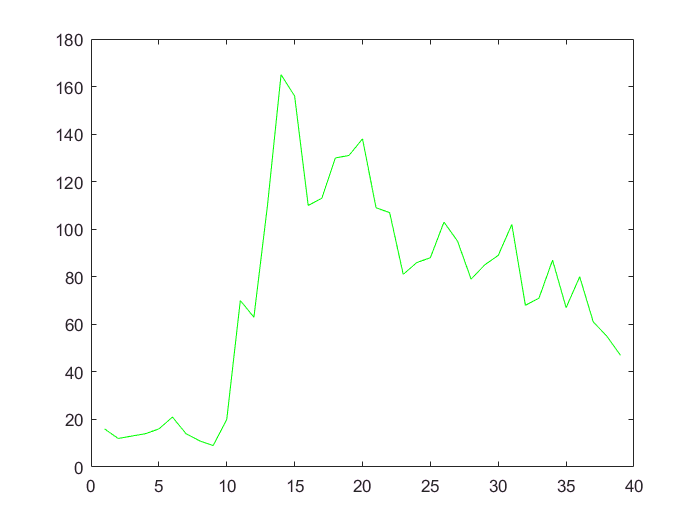


figure;
plot(data.greenmax, 'g');

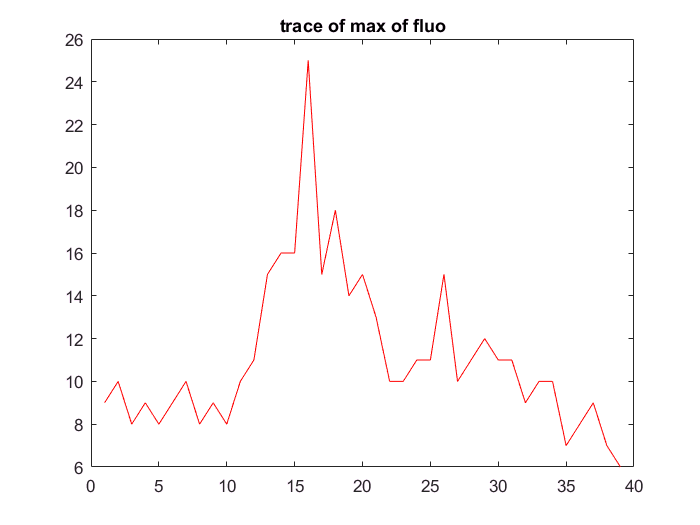

figure
plot(data.redmax, 'r');
title('trace of max of fluo');

% sets up variables for cross correlation on real data

max_delay = 25;
project = 'real data sum';
trace1 = cell([1 length(preprocessed)]);
trace2 = cell([1 length(preprocessed)]);
for i = 1:length(preprocessed)
    trace1{i} = preprocessed(i).greensum;
    trace2{i} = preprocessed(i).redsum;
end

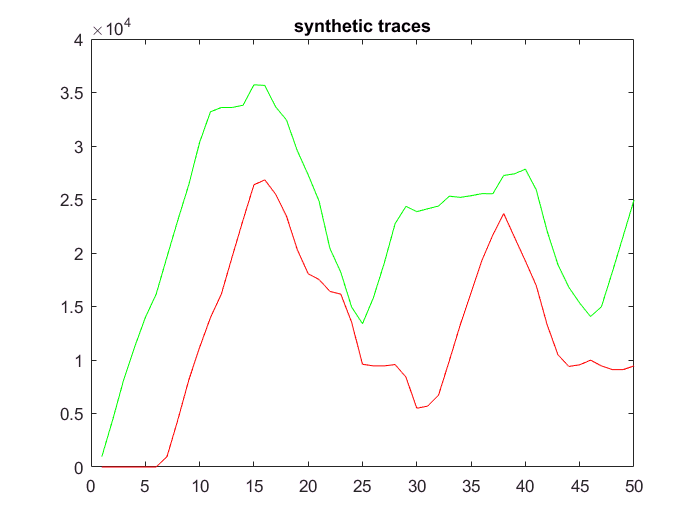

% plots synthetic data (manually add time delay)
tr = 14;
figure;
plot(data.fluo_data{1}{tr}, 'g');
hold on;
plot(data.fluo_data{2}{tr}, 'r');
title('synthetic traces');

% sets up variables for cross correlation on synthetic data

max_delay = 30;
project = 'eve-like-dT40w15w9n0';
trace1 = data.fluo_data{1};
trace2 = data.fluo_data{2};
